# Repeat Reunion Part 2: Stranger vs. Cagemate interactions by degu

Updates 5/2024: Statistical tests now include both repeated measures ANOVA as well as Generalized Linear Multi-effect Models

conditionmat_f = RR_OrgData(rdb_rr, sumbehav, fem_pairs);
conditionmat_m = RR_OrgData(rdb_rr, sumbehav, mal_pairs);

colorcodes_fem = [.75 0 0 ; .4 0 0 ; 1 .35 .35];
colorcodes_f = colorcodes_fem;
colorcodes_mal = [0 0 .75 ; 0 0 .4 ; .35 .35 1];
colorcodes_m = colorcodes_mal;

## I. Stranger Vs Cagemate: overall differences

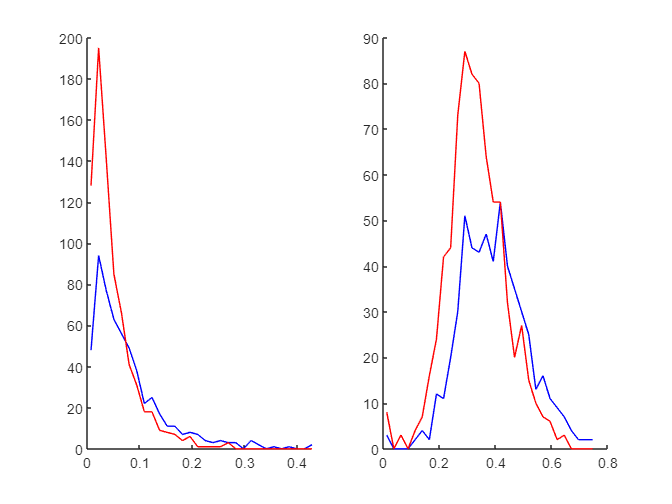



%first gauge the distribution--is it similar to the one of both degus?
%(answer is yes--good to use the cubed root)

fall = reshape(dtt(:,6:end),[],1);
mall = reshape(dttM(:,6:end), [], 1);

figure
subplot(1,2,1)
[am bm] = hist(mall, 30);
[af bf] = hist(fall, bm);

[amt bmt] = hist(mall.^(1/3), 30);
[aft bft] = hist(fall.^(1/3), bmt);

plot(bm,am, 'b')
hold on
plot(bf,af, 'r')
box off

subplot(1,2,2)
plot(bmt,amt, 'b')
hold on
plot(bft,aft, 'r')

box off

### Cagemate versus strangers

allbyday_f = cat(3,dtt(:,6:10), dtt(:,11:15)).^(1/3);
allbyday_m = cat(3,dttM(:,6:10), dttM(:,11:15)).^(1/3);

allbyday_ct = [allbyday_f ; allbyday_m];

allbyday_ct_notransform = [allbyday_f ; allbyday_m];

femmalvec = [ones(size(allbyday_f,1),1) ; 2*ones(size(allbyday_m,1),1)];


[tbl,rm] = simple_mixed_anova(allbyday_ct, femmalvec, {'exposureday' 'cagstr'}, {'sex'})

tbl = 12×8 table
                                       SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         120.99      1       120.99     2768.2    1.5603e-71    1.5603e-71    1.5603e-71    1.5603e-71
    sex                                0.54512      1      0.54512     12.472    0.00064221    0.00064221    0.00064221    0.00064221
    Error                               4.1086     94     0.043708                                                         

rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [96×11 table]
         ResponseNames: {'Y001'  'Y002'  'Y003'  'Y004'  'Y005'  'Y006'  'Y007'  'Y008'  'Y009'  'Y010'}
    BetweenFactorNames: {'sex'}
          BetweenModel: '1 + sex'

   Within Subjects:
          WithinDesign: [10×2 table]
     WithinFactorNames: {'exposureday'  'cagstr'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [2×10 table]
            Covariance: [10×10 table]


%repeat using GLM
%
% degunum = random effect (grouping variable)
% days = fixed (RM)
% strcag = fixed (NRM)
% sex = fixed (NRM)
%
%
%
% formula: 
%  'y ~ 1 + strcag + sex + days + (1 | degunum) +  strcag:sex:days'
%     includes random intercept for degu number 
% will treat variable as categorical 
%

% Include cube-root transformed responses, untransformed, non-zero modified
% (for gamma distribution)
y_abd = reshape(allbyday_ct_notransform, [], 1,1);
y_abdN0 = y_abd;
y_abdN0(y_abdN0 == 0) = 0.0001;
y_abdCR = y_abd.^(1/3);

% Linearize the matrices
lin_sex = reshape(repmat(femmalvec-1, 5, 2), [], 1, 1);
strcag = cat(3, zeros(size(allbyday_ct,1), size(allbyday_ct,2)), ones(size(allbyday_ct,1), size(allbyday_ct,2)));
lin_strcag = reshape(strcag, [], 1, 1);
lin_days = reshape(repmat(1:5, size(allbyday_ct, 1), size(allbyday_ct,3)), [],1,1);
degunum = repmat([1:size(allbyday_ct,1)]', 1, size(allbyday_ct, 2), size(allbyday_ct,3));
lin_degunum = reshape(degunum, [], 1, 1);

%create table
abd_T = table(lin_degunum, lin_days, lin_strcag, lin_sex, y_abd, y_abdN0, y_abdCR, lin_degunum_STR);

% Run the model
%glme_CR = fitglme(abd_T, 'y_abdCR ~ 1 + lin_strcag + lin_sex + lin_days + lin_strcag:lin_sex + lin_strcag:lin_days + lin_sex:lin_days + lin_strcag:lin_sex:lin_days + (1 | lin_degunum)')
glme_CRs = fitglme(abd_T, 'y_abdCR ~ 1 + lin_strcag + lin_sex + lin_days + lin_strcag:lin_sex + lin_strcag:lin_days + lin_sex:lin_days + lin_strcag:lin_sex:lin_days + (1 | lin_degunum_STR)');
[~, ~, stats_all] = fixedEffects(glme_CRs)

stats_all =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                                   Estimate      SE           tStat       DF     pValue        Lower         Upper    
    {'(Intercept)'                }           0.65778     0.013622      48.288    952    3.366e-258       0.63105      0.68451
    {'lin_days'                   }         0.0031519    0.0036497     0.86361    952       0.38802    -0.0040104     0.010314
    {'lin_strcag'                 }           0.03716     0.017118      2.1707    952      0.030198     0.0035654     0.070754
    {'lin_sex'                    }          0.014235     0.020121     0.70748    952       0.47944     -0.025252     0.053722
    {'lin_days:lin_strcag'        }        -0.0037641    0.0051614    -0.72928    952       0.46601     -0.013893    0.0063649
    {'lin_days:lin_sex'           }         0.0050649    0.0053909     0.93953    952        0.3477    -0.0055145     0.015644
    {'lin_strc


%% Re-run as a gamma distribution without zeros
%glme_N0 = fitglme(abd_T, 'y_abdN0 ~ 1 + lin_strcag + lin_sex + lin_days + lin_strcag:lin_sex + lin_strcag:lin_days + lin_sex:lin_days + lin_strcag:lin_sex:lin_days + (1 | lin_degunum)', 'Distribution', 'gamma');


#### Run within sex group


for j = 1:2
    if j == 1
      abdT = allbyday_f;
    else
      abdT = allbyday_m;        
    end
        
    [tbl,rm] = simple_mixed_anova(abdT, [], {'exposureday' 'cagstr'})

    % Include cube-root transformed responses, untransformed, non-zero modified
    % (for gamma distribution)
    y_abd = reshape(abdT, [], 1,1);
    y_abdN0 = y_abd;
    y_abdN0(y_abdN0 == 0) = 0.0001;
    y_abdCR = y_abd.^(1/3);

    % Linearize the matrices
%    lin_sex = reshape(repmat(femmalvec-1, 5, 2), [], 1, 1);
    strcag = cat(3, zeros(size(abdT,1), size(abdT,2)), ones(size(abdT,1), size(abdT,2)));
    lin_strcag = reshape(strcag, [], 1, 1);
    lin_days = reshape(repmat(1:5, size(abdT, 1), size(abdT,3)), [],1,1);
    degunum = repmat([1:size(abdT,1)]', 1, size(abdT, 2), size(abdT,3));
    lin_degunum = reshape(degunum, [], 1, 1);

    %create table
    abdT_T = table(lin_degunum, lin_days, lin_strcag, y_abdCR);

    % Run the model
    %glme_CR = fitglme(abd_T, 'y_abdCR ~ 1 + lin_strcag + lin_sex + lin_days + lin_strcag:lin_sex + lin_strcag:lin_days + lin_sex:lin_days + lin_strcag:lin_sex:lin_days + (1 | lin_degunum)')
    glme_CRs = fitglme(abdT_T, 'y_abdCR ~ 1 + lin_strcag + lin_days + lin_strcag:lin_days + (1 | lin_degunum)');
    [~, ~, stats_T] = fixedEffects(glme_CRs)
end

tbl = 8×8 table
                                       SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         57.435      1       57.435     1213.1    3.1813e-37    3.1813e-37    3.1813e-37    3.1813e-37
    Error                               2.4147     51     0.047347                                                                   
    (Intercept):exposureday           0.043147      4     0.010787     1.7066       0.14986       0.17279       0.16954     

rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [52×10 table]
         ResponseNames: {'Y001'  'Y002'  'Y003'  'Y004'  'Y005'  'Y006'  'Y007'  'Y008'  'Y009'  'Y010'}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [10×2 table]
     WithinFactorNames: {'exposureday'  'cagstr'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×10 table]
            Covariance: [10×10 table]


stats_T =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate      SE           tStat       DF     pValue         Lower         Upper    
    {'(Intercept)'        }           0.65778     0.014773      44.527    516    7.0744e-179       0.62876       0.6868
    {'lin_days'           }         0.0031519    0.0039179     0.80447    516        0.42149    -0.0045452     0.010849
    {'lin_strcag'         }           0.03716     0.018377      2.0221    516       0.043682     0.0010572     0.073262
    {'lin_days:lin_strcag'}        -0.0037641    0.0055408    -0.67935    516        0.49722     -0.014649    0.0071212


tbl = 8×8 table
                                       SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         63.592      1       63.592     1614.3    9.7838e-36    9.7838e-36    9.7838e-36    9.7838e-36
    Error                               1.6939     43     0.039392                                                                   
    (Intercept):exposureday           0.025064      4     0.006266    0.67451       0.61051       0.58224       0.59496     

rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [44×10 table]
         ResponseNames: {'Y001'  'Y002'  'Y003'  'Y004'  'Y005'  'Y006'  'Y007'  'Y008'  'Y009'  'Y010'}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [10×2 table]
     WithinFactorNames: {'exposureday'  'cagstr'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×10 table]
            Covariance: [10×10 table]


stats_T =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate     SE           tStat      DF     pValue         Lower        Upper     
    {'(Intercept)'        }          0.67201     0.013178     50.994    436    7.4324e-186      0.64611       0.69792
    {'lin_days'           }        0.0082168    0.0035925     2.2872    436       0.022663    0.0011559      0.015278
    {'lin_strcag'         }         0.073107      0.01685     4.3386    436     1.7837e-05     0.039989       0.10623
    {'lin_days:lin_strcag'}         -0.01205    0.0050806    -2.3717    436       0.018139    -0.022035    -0.0020643


### Main Figure


figure
sp1 = subplot(1,5,1:3)

sp1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.4494 0.8150]
            Units: 'normalized'

  Show all properties


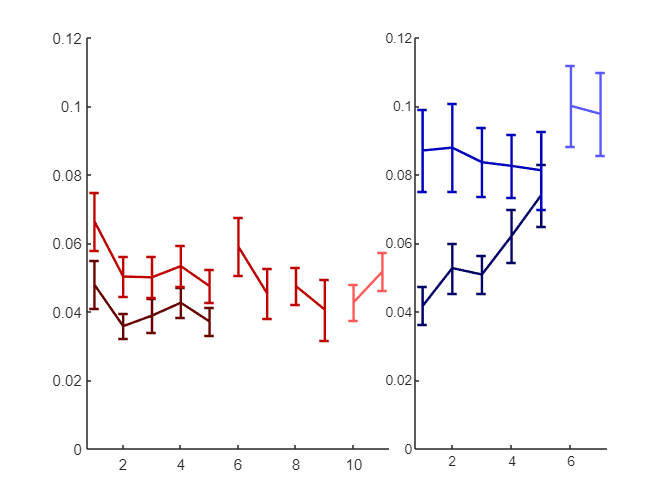

%sp1 = subplot(1,2,1); %UNCOMMENT FOR THATCHER & INSEL 2023 FIGURES
hold on

% randselect = randperm(size(dtt,1), 10);
% for i = 1:length(randselect)
%     plot(1:5, dtt(randselect(i), 6:10), 'Color', [1 .90 .90], 'LineStyle', '--');        
% 
%     plot(1:5, dtt(randselect(i), 11:15), 'Color', [1 .90 .90]);
% 
% %    plot(1:5, dtt(randselect(i), 16:20), 'Color', [1 .95 .90], 'LineStyle', ':');
% end

errorbar(1:5,nanmean(dtt(:, 6:10)), nanstd(dtt(:, 6:10))/sqrt(length(dtt)), 'Color', colorcodes_fem(2,:), 'LineWidth', 1.5);
errorbar(1:5,nanmean(dtt(:, 11:15)), nanstd(dtt(:, 11:15))/sqrt(length(dtt)), 'Color', colorcodes_fem(1,:), 'LineWidth', 1.5 );
errorbar(6:7, nanmean(dtt(:,21:22)), nanstd(dtt(:, 21:22))/sqrt(length(find(~isnan(dtt(:,22))))), 'Color', colorcodes_fem(1,:), 'LineWidth', 1.5); %COMMENT-OUT FOR THATCHER & INSEL 2023 FIGURES
errorbar(8:9, nanmean(dtt(:,23:24)), nanstd(dtt(:, 23:24))/sqrt(length(find(~isnan(dtt(:,22))))), 'Color', colorcodes_fem(1,:), 'LineWidth', 1.5);%COMMENT-OUT FOR THATCHER & INSEL 2023 FIGURES
errorbar(10:11,nanmean(dtt(:, 16:17)), nanstd(dtt(:, 16:17))/sqrt(length(dtt)), 'Color', colorcodes_fem(3,:), 'LineWidth', 1.5 );%COMMENT-OUT FOR THATCHER & INSEL 2023 FIGURES
set(sp1, 'XLim', [.75 11.25]); 
box off
%set(sp1, 'XLim', [.75 11.25]); %UNCOMMENT FOR THATCHER & INSEL 2023 FIGURES


sp2 = subplot(1,5,4:5);
%sp2 = subplot(1,2,1); %UNCOMMENT FOR THATCHER & INSEL 2023 FIGURES
hold on

% randselect = randperm(size(dttM,1), 10);
% for i = 1:length(randselect)
%     plot(1:5, dttM(randselect(i), 6:10), 'Color', [.90 .90 1], 'LineStyle', '--');        
% 
%     plot(1:5, dttM(randselect(i), 11:15), 'Color', [.90 .90 1]);
% 
%  %   plot(1:5, dttM(randselect(i), 16:20), 'Color', [.9 .95 1], 'LineStyle', ':');
% end


errorbar(1:5,nanmean(dttM(:, 6:10)), nanstd(dttM(:, 6:10))/sqrt(length(dttM)), 'Color', colorcodes_mal(2,:), 'LineWidth', 1.5);
errorbar(1:5,nanmean(dttM(:, 11:15)), nanstd(dttM(:, 11:15))/sqrt(length(dttM)), 'Color', colorcodes_mal(1,:), 'LineWidth', 1.5 );
errorbar(6:7,nanmean(dttM(:, 16:17)), nanstd(dttM(:, 16:17))/sqrt(length(dttM)), 'Color', colorcodes_mal(3,:), 'LineWidth', 1.5 );%COMMENT-OUT FOR THATCHER & INSEL 2023 FIGURES

box off
set(sp2, 'XLim', [.75 7.25]); %COMMENT-OUT FOR THATCHER & INSEL 2023 FIGURES
%set(sp2, 'XLim', [.75 5.25]); %UNCOMMENT FOR THATCHER & INSEL 2023 FIGURES
ylim1 = get(sp1, 'YLim');
ylim2 = get(sp2, 'YLim');
maxlims = max([ylim1 ; ylim2]);
set(sp1, 'YLim', [0 maxlims(2)-.0]);
set(sp2, 'YLim', [0 maxlims(2)-.0]);

## II. S v C: Individual interactions

figure
clear tbl
clear sp1 sp2

stats_t = cell(5,1);
stats_a = cell(5,2);
   
for i = 1:5

    fprintf('interaction type %d --- BOTH SEXES', i)
    ABD_bs_f = cat(3,degutable(:,6:10,i), degutable(:,11:15,i)).^(1/3);
    ABD_bs_m = cat(3,degutableM(:,6:10,i), degutableM(:,11:15,i)).^(1/3);
    ABD_bs = [ABD_bs_f ; ABD_bs_m];

    sexvec = [zeros(size(ABD_bs_f,1), 1); ones(size(ABD_bs_m,1),1)];

    tbl_bs = simple_mixed_anova(ABD_bs, sexvec, {'exposureday' 'cagstr'}, {'sex'})

    %now GLMM
    y_abd = reshape(ABD_bs, [],1);
    strcag = cat(3, zeros(size(ABD_bs,1), size(ABD_bs,2)), ones(size(ABD_bs,1), size(ABD_bs,2)));
    lin_strcag = reshape(strcag, [], 1, 1);
    lin_days = reshape(repmat(1:5, size(ABD_bs, 1), size(ABD_bs,3)), [],1,1);
    degunum = repmat([1:size(ABD_bs,1)]', 1, size(ABD_bs, 2), size(ABD_bs,3));
    lin_degunum = reshape(degunum, [], 1, 1);
    lin_sex = reshape(repmat(sexvec-1, 5, 2), [], 1, 1);

    abd_T_I = table(lin_degunum, lin_days, lin_strcag, lin_sex, y_abd);
    glme_I = fitglme(abd_T_I, 'y_abd ~ 1 + lin_strcag + lin_days + lin_sex + lin_strcag:lin_sex + lin_strcag:lin_days + lin_sex:lin_days + lin_sex:lin_days:lin_strcag + (1 | lin_degunum)');

    [~, ~, stats_t{i}] = fixedEffects(glme_I);
    stats_t{i}
    

    for j = 1:2
        if j == 1
            degutableT = degutable;
           colorcodesT = colorcodes_f;
        else
            degutableT = degutableM;
             colorcodesT = colorcodes_m;
        end

    
    allbyday = cat(3,degutableT(:,6:10,i), degutableT(:,11:15,i)).^(1/3);
    
    fprintf('\n \n interaction type %d, sex %d', i, j)
    tbl{i,j} = simple_mixed_anova(allbyday, [], {'exposureday' 'cagstr'});
    tbl{i,j}

    y_abd = reshape(allbyday, [],1);
    strcag = cat(3, zeros(size(allbyday,1), size(allbyday,2)), ones(size(allbyday,1), size(allbyday,2)));
    lin_strcag = reshape(strcag, [], 1, 1);
    lin_days = reshape(repmat(1:5, size(allbyday, 1), size(allbyday,3)), [],1,1);
    degunum = repmat([1:size(allbyday,1)]', 1, size(allbyday, 2), size(allbyday_ct,3));
    lin_degunum = reshape(degunum, [], 1, 1);

    abd_T_I = table(lin_degunum, lin_days, lin_strcag, y_abd);
    glme_I = fitglme(abd_T_I, 'y_abd ~ 1 + lin_strcag + lin_days + lin_strcag:lin_days + (1 | lin_degunum)');
    [~, ~, stats_a{i,j}] = fixedEffects(glme_I);
    stats_a{i,j}
if j == 1 & i == 3
    dbs = 1;
end

    %% Days 1-5 figures
%     subplot(5,2,j+(i-1)*2);     
%     e1 = errorbar(1:5, nanmean(degutableT(:,11:15, i)), nanstd(degutableT(:,11:15,i))/sqrt(length(degutableT)-1), 'Color', colorcodesT(1,:));
%     hold on
%     e2 = errorbar(1:5, nanmean(degutableT(:,6:10,i)), nanstd(degutableT(:,6:10,i))/sqrt(length(degutableT)-1), 'Color', colorcodesT(2,:));
%     errorbar(1:2, nanmean(degutableT(:,16:17,i)), nanstd(degutableT(:,16:17,i))/sqrt(length(degutableT)-1), 'Color', colorcodesT(3,:));
%     set(get(e1, 'parent'), 'XLim', [0.75 5.25])
%     box off

    %% Alldays figures
    if j == 1
        sp1{i} = subplot(5,5, [1:3] + (i-1)*5);
    elseif j == 2
        sp2{i} = subplot(5,5, [4:5] + (i-1)*5);
    end
    hold on

        e1 = errorbar(1:5, nanmean(degutableT(:,11:15, i)), nanstd(degutableT(:,11:15,i))/sqrt(length(degutableT)-1), 'Color', colorcodesT(1,:));
        e2 = errorbar(1:5, nanmean(degutableT(:,6:10,i)), nanstd(degutableT(:,6:10,i))/sqrt(length(degutableT)-1), 'Color', colorcodesT(2,:));

        if j == 1
            errorbar(6:7, nanmean(degutableT(:,21:22,i)), nanstd(degutableT(:, 21:22,i))/sqrt(length(find(~isnan(degutableT(:,21,i))))-1), 'Color', colorcodesT(1,:));
            errorbar(8:9, nanmean(degutableT(:,23:24,i)), nanstd(degutableT(:, 23:24,i))/sqrt(length(find(~isnan(degutableT(:,23,i))))-1), 'Color', colorcodesT(1,:));
            errorbar(10:11, nanmean(degutableT(:,16:17,i)), nanstd(degutableT(:,16:17,i))/sqrt(length(find(~isnan(degutableT(:,16,i))))-1), 'Color', colorcodesT(3,:));
            set(get(e1, 'parent'), 'XLim', [0.75 11.25])
        elseif j == 2
            errorbar(6:7, nanmean(degutableT(:,16:17,i)), nanstd(degutableT(:,16:17,i))/sqrt(length(find(~isnan(degutableT(:,17,i))))-1), 'Color', colorcodesT(3,:));
             set(get(e1, 'parent'), 'XLim', [0.75 7.25])
        end



    box off
    
%     if i == 4 & j == 2
%         [a b] = ttest(degutableT(:,6,i) - degutableT(:,11,i))
%     elseif i == 1 & j == 2
%         [a b] = ttest(degutableT(:,6,i) - degutableT(:,11,i))
%         [a2 b2] = ttest(degutableT(:,7,i) - degutableT(:,12,i))
%         [a2 b3] = ttest(degutableT(:,8,i) - degutableT(:,13,i))
%         [a2 b4] = ttest(degutableT(:,9,i) - degutableT(:,14,i))
%         [a2 b5] = ttest(degutableT(:,10,i) - degutableT(:,15,i))
%         fdr_bh([b b2 b3 b4 b5])
%     end
%     
    
 % 
end
end

interaction type 1 --- BOTH SEXES

tbl_bs = 12×8 table
                                       SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    ______    __________    __________    __________    __________

    (Intercept)                         8.5229      1       8.5229    143.84     1.181e-20     1.181e-20     1.181e-20     1.181e-20
    sex                                 1.0198      1       1.0198    17.211    7.3374e-05    7.3374e-05    7.3374e-05    7.3374e-05
    Error                               5.5698     94     0.059253                                                          

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                                   Estimate     SE           tStat      DF     pValue        Lower         Upper     
    {'(Intercept)'                }         0.056985     0.019345     2.9457    952     0.0033009      0.019021      0.094949
    {'lin_days'                   }         0.013321    0.0049232     2.7058    952     0.0069365     0.0036594      0.022983
    {'lin_strcag'                 }           0.1005     0.023092     4.3524    952    1.4924e-05      0.055187       0.14582
    {'lin_sex'                    }         0.021546     0.026285     0.8197    952       0.41259     -0.030037      0.073129
    {'lin_days:lin_strcag'        }        -0.013294    0.0069625    -1.9094    952      0.056507     -0.026958    0.00036919
    {'lin_days:lin_sex'           }         0.010345    0.0066893     1.5465    952       0.12231    -0.0027822      0.023473
    {'lin_strcag:lin_sex'  


 
 interaction type 1, sex 1

ans = 8×8 table
                                       SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    ______    __________    __________    __________    __________

    (Intercept)                         1.9889      1       1.9889    50.828    3.3995e-09    3.3995e-09    3.3995e-09    3.3995e-09
    Error                               1.9957     51     0.039131                                                                  
    (Intercept):exposureday            0.01373      4    0.0034325    0.6097        0.6561       0.64913        0.6561       0.4

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate      SE          tStat       DF     pValue      Lower         Upper    
    {'(Intercept)'        }          0.035439    0.014518       2.441    516    0.014981     0.0069171     0.063961
    {'lin_days'           }         0.0029757    0.003701     0.80403    516     0.42175    -0.0042952     0.010247
    {'lin_strcag'         }           0.04192    0.017359      2.4149    516    0.016088     0.0078166     0.076024
    {'lin_days:lin_strcag'}        -0.0023205    0.005234    -0.44336    516     0.65769     -0.012603    0.0079621



 
 interaction type 1, sex 2

ans = 8×8 table
                                       SumSq      DF      MeanSq       F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    ________    ______    __________    __________    __________    __________

    (Intercept)                         7.1257      1      7.1257    85.728    8.4693e-12    8.4693e-12    8.4693e-12    8.4693e-12
    Error                               3.5742     43     0.08312                                                                  
    (Intercept):exposureday            0.07287      4    0.018218    1.2596       0.28784       0.29065       0.28979       0.26796


ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate     SE           tStat      DF     pValue        Lower        Upper    
    {'(Intercept)'        }         0.056985      0.02285     2.4939    436      0.013006     0.012075       0.1019
    {'lin_days'           }         0.013321    0.0058096     2.2929    436      0.022327    0.0019027     0.024739
    {'lin_strcag'         }           0.1005     0.027249     3.6883    436    0.00025427     0.046948      0.15406
    {'lin_days:lin_strcag'}        -0.013294     0.008216    -1.6181    436       0.10636    -0.029442    0.0028536


interaction type 2 --- BOTH SEXES

tbl_bs = 12×8 table
                                        SumSq       DF       MeanSq          F          pValue       pValueGG      pValueHF      pValueLB 
                                      __________    ___    __________    _________    __________    __________    __________    __________

    (Intercept)                           1.7131      1        1.7131       103.08    8.7136e-17    8.7136e-17    8.7136e-17    8.7136e-17
    sex                               3.1401e-05      1    3.1401e-05    0.0018894       0.96542       0.96542       0.96542       0.96542
    Error                                 1.5622     94       0.01662                               

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                                   Estimate      SE           tStat       DF     pValue        Lower         Upper    
    {'(Intercept)'                }          0.046558     0.012067      3.8584    952    0.00012184      0.022878     0.070239
    {'lin_days'                   }         -0.003437    0.0032958     -1.0428    952       0.29729    -0.0099049    0.0030309
    {'lin_strcag'                 }          0.033884     0.015459      2.1919    952       0.02863     0.0035465     0.064221
    {'lin_sex'                    }          0.015045     0.016396     0.91763    952       0.35905     -0.017131     0.047221
    {'lin_days:lin_strcag'        }        -0.0070782     0.004661     -1.5186    952       0.12919     -0.016225    0.0020688
    {'lin_days:lin_sex'           }        -0.0057207    0.0044781     -1.2775    952       0.20175     -0.014509    0.0030674
    {'lin_strcag:lin


 
 interaction type 2, sex 1

ans = 8×8 table
                                        SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      _________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         0.92642      1      0.92642     58.121    5.6532e-10    5.6532e-10    5.6532e-10    5.6532e-10
    Error                               0.81292     51      0.01594                                                                   
    (Intercept):exposureday            0.011044      4    0.0027609    0.63284       0.63962       0.62513        0.6381

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate      SE           tStat       DF     pValue       Lower         Upper    
    {'(Intercept)'        }          0.031513     0.010707      2.9432    516    0.0033949      0.010478     0.052548
    {'lin_days'           }         0.0022837    0.0029083     0.78525    516      0.43267    -0.0034298    0.0079973
    {'lin_strcag'         }          0.018928     0.013641      1.3876    516      0.16587     -0.007871     0.045727
    {'lin_days:lin_strcag'}        -0.0037463    0.0041129    -0.91087    516      0.36279     -0.011826    0.0043338



 
 interaction type 2, sex 2

ans = 8×8 table
                                       SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    ______    __________    __________    __________    __________

    (Intercept)                        0.79744      1      0.79744    45.761    2.8229e-08    2.8229e-08    2.8229e-08    2.8229e-08
    Error                              0.74933     43     0.017426                                                                  
    (Intercept):exposureday            0.04502      4     0.011255    2.6122      0.037154      0.045708      0.040269       0.1

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate      SE           tStat      DF     pValue        Lower        Upper    
    {'(Intercept)'        }          0.046558     0.012553      3.709    436    0.00023491     0.021887     0.071229
    {'lin_days'           }         -0.003437    0.0034477    -0.9969    436       0.31936    -0.010213    0.0033391
    {'lin_strcag'         }          0.033884     0.016171     2.0953    436      0.036717    0.0021009     0.065666
    {'lin_days:lin_strcag'}        -0.0070782    0.0048757    -1.4517    436        0.1473    -0.016661    0.0025046


interaction type 3 --- BOTH SEXES

tbl_bs = 12×8 table
                                       SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         17.597      1       17.597     494.97    3.1184e-39    3.1184e-39    3.1184e-39    3.1184e-39
    sex                               0.014325      1     0.014325    0.40292       0.52713       0.52713       0.52713       0.52713
    Error                               3.3419     94     0.035552                                                      

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                                   Estimate     SE           tStat      DF     pValue        Lower         Upper     
    {'(Intercept)'                }          0.10461     0.016482     6.3465    952    3.4017e-10       0.07226       0.13695
    {'lin_days'                   }        0.0075037     0.004388       1.71    952      0.087583    -0.0011076      0.016115
    {'lin_strcag'                 }         0.055071     0.020582     2.6757    952     0.0075843      0.014681      0.095462
    {'lin_sex'                    }        -0.042556     0.022395    -1.9003    952        0.0577     -0.086505     0.0013928
    {'lin_days:lin_strcag'        }        -0.015112    0.0062056    -2.4351    952      0.015069      -0.02729    -0.0029333
    {'lin_days:lin_sex'           }         0.014717    0.0059622     2.4685    952      0.013745     0.0030168      0.026418
    {'lin_strcag:lin_sex'  


 
 interaction type 3, sex 1

ans = 8×8 table
                                       SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    ______    __________    __________    __________    __________

    (Intercept)                         10.154      1       10.154    243.53     4.633e-21     4.633e-21     4.633e-21     4.633e-21
    Error                               2.1264     51     0.041694                                                                  
    (Intercept):exposureday            0.05927      4     0.014817    1.8144       0.12737       0.14774       0.14358       0.1

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate      SE           tStat      DF     pValue       Lower         Upper     
    {'(Intercept)'        }           0.14716     0.014669     10.032    516    9.315e-22       0.11834       0.17598
    {'lin_days'           }        -0.0072136    0.0036951    -1.9522    516     0.051454     -0.014473    4.5689e-05
    {'lin_strcag'         }          0.020521     0.017331      1.184    516      0.23695     -0.013528       0.05457
    {'lin_days:lin_strcag'}         0.0026373    0.0052256    0.50469    516      0.61399    -0.0076288      0.012903



 
 interaction type 3, sex 2

ans = 8×8 table
                                       SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         7.6648      1       7.6648     271.16    3.4982e-20    3.4982e-20    3.4982e-20    3.4982e-20
    Error                               1.2155     43     0.028266                                                                   
    (Intercept):exposureday           0.012189      4    0.0030472    0.26694        0.8989       0.89475        0.8989     

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate     SE           tStat     DF     pValue        Lower         Upper     
    {'(Intercept)'        }          0.10461     0.017093    6.1196    436    2.0912e-09      0.071009        0.1382
    {'lin_days'           }        0.0075037    0.0047896    1.5667    436       0.11792    -0.0019099      0.016917
    {'lin_strcag'         }         0.055071     0.022465    2.4514    436      0.014622      0.010918      0.099225
    {'lin_days:lin_strcag'}        -0.015112    0.0067736    -2.231    436      0.026191     -0.028424    -0.0017987


interaction type 4 --- BOTH SEXES

tbl_bs = 12×8 table
                                        SumSq      DF       MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      _________    ___    __________    _______    __________    __________    __________    __________

    (Intercept)                           27.84      1         27.84     546.48    6.0132e-41    6.0132e-41    6.0132e-41    6.0132e-41
    sex                                0.015482      1      0.015482    0.30391       0.58275       0.58275       0.58275       0.58275
    Error                                4.7887     94      0.050944                                            

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                                   Estimate       SE           tStat         DF     pValue        Lower        Upper   
    {'(Intercept)'                }            0.11047     0.017259         6.401    952      2.42e-10     0.076604     0.14434
    {'lin_days'                   }           0.021738    0.0042954        5.0609    952    5.0071e-07     0.013309    0.030168
    {'lin_strcag'                 }        -7.1195e-05     0.020147    -0.0035337    952       0.99718    -0.039609    0.039467
    {'lin_sex'                    }          -0.033476      0.02345       -1.4276    952       0.15375    -0.079497    0.012544
    {'lin_days:lin_strcag'        }        -0.00049086    0.0060746     -0.080805    952       0.93561    -0.012412     0.01143
    {'lin_days:lin_sex'           }           0.016512    0.0058363        2.8293    952     0.0047632     0.005059    0.027966
    {'lin_str


 
 interaction type 4, sex 1

ans = 8×8 table
                                       SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         14.478      1       14.478     483.78    1.1002e-27    1.1002e-27    1.1002e-27    1.1002e-27
    Error                               1.5262     51     0.029926                                                                   
    (Intercept):exposureday            0.03929      4    0.0098225     1.8715       0.11676       0.12957        0.1243     

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate      SE           tStat      DF     pValue        Lower         Upper   
    {'(Intercept)'        }           0.14395     0.013136     10.958    516    2.8858e-25       0.11814     0.16976
    {'lin_days'           }          0.005226    0.0034075     1.5337    516       0.12572    -0.0014683     0.01192
    {'lin_strcag'         }          0.012594     0.015983    0.78799    516       0.43106     -0.018805    0.043994
    {'lin_days:lin_strcag'}        0.00062132     0.004819    0.12893    516       0.89746    -0.0088459    0.010089



 
 interaction type 4, sex 2

ans = 8×8 table
                                        SumSq       DF       MeanSq         F          pValue       pValueGG      pValueHF      pValueLB 
                                      __________    ___    __________    ________    __________    __________    __________    __________

    (Intercept)                           13.462      1        13.462      177.43    7.3543e-17    7.3543e-17    7.3543e-17    7.3543e-17
    Error                                 3.2625     43      0.075872                                                                    
    (Intercept):exposureday              0.46038      4        0.1151      9.9036    3.1014e-07    3.3078e-0

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate       SE           tStat         DF     pValue        Lower        Upper   
    {'(Intercept)'        }            0.11047     0.020221        5.4633    436    7.8711e-08     0.070731     0.15022
    {'lin_days'           }           0.021738    0.0049028        4.4339    436    1.1728e-05     0.012102    0.031375
    {'lin_strcag'         }        -7.1195e-05     0.022996    -0.0030959    436       0.99753    -0.045268    0.045126
    {'lin_days:lin_strcag'}        -0.00049086    0.0069336     -0.070794    436       0.94359    -0.014118    0.013137


interaction type 5 --- BOTH SEXES

tbl_bs = 12×8 table
                                        SumSq       DF       MeanSq         F          pValue       pValueGG      pValueHF      pValueLB 
                                      __________    ___    __________    ________    __________    __________    __________    __________

    (Intercept)                           74.663      1        74.663      3017.1    3.0954e-73    3.0954e-73    3.0954e-73    3.0954e-73
    sex                                  0.11167      1       0.11167      4.5127      0.036268      0.036268      0.036268      0.036268
    Error                                 2.3262     94      0.024746                                   

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                                   Estimate     SE           tStat       DF     pValue        Lower         Upper      
    {'(Intercept)'                }          0.24959     0.013662      18.269    952    3.7732e-64       0.22278         0.2764
    {'lin_days'                   }        0.0093359    0.0036274      2.5737    952      0.010212     0.0022173       0.016455
    {'lin_strcag'                 }         0.082693     0.017014      4.8603    952    1.3705e-06      0.049304        0.11608
    {'lin_sex'                    }        -0.017431     0.018563    -0.93903    952       0.34795     -0.053861       0.018998
    {'lin_days:lin_strcag'        }        -0.018846      0.00513     -3.6737    952    0.00025239     -0.028913     -0.0087786
    {'lin_days:lin_sex'           }         0.012766    0.0049287      2.5902    952     0.0097398     0.0030937       0.022438
    {'lin_str


 
 interaction type 5, sex 1

ans = 8×8 table
                                        SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      _________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                          37.636      1       37.636     1205.5    3.7048e-37    3.7048e-37    3.7048e-37    3.7048e-37
    Error                                1.5922     51     0.031219                                                                   
    (Intercept):exposureday            0.076029      4     0.019007     3.5568     0.0078922      0.017274      0.015116

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate      SE           tStat      DF     pValue        Lower         Upper    
    {'(Intercept)'        }           0.26702     0.012343     21.634    516    2.3622e-74       0.24277      0.29127
    {'lin_days'           }        -0.0034302    0.0030571     -1.122    516       0.26237    -0.0094361    0.0025757
    {'lin_strcag'         }          0.040066     0.014339     2.7942    516     0.0053964      0.011896     0.068237
    {'lin_days:lin_strcag'}        -0.0051565    0.0043234    -1.1927    516       0.23353      -0.01365    0.0033371



 
 interaction type 5, sex 2

ans = 8×8 table
                                       SumSq      DF      MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    ___    _________    _______    __________    __________    __________    __________

    (Intercept)                         37.177      1       37.177       2178    1.8012e-38    1.8012e-38    1.8012e-38    1.8012e-38
    Error                              0.73398     43     0.017069                                                                   
    (Intercept):exposureday           0.006497      4    0.0016243    0.23889       0.91603       0.88362       0.89815     

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate     SE           tStat     DF     pValue        Lower        Upper     
    {'(Intercept)'        }          0.24959     0.013945    17.898    436    4.1208e-54      0.22218         0.277
    {'lin_days'           }        0.0093359    0.0039567    2.3595    436      0.018738    0.0015594      0.017113
    {'lin_strcag'         }         0.082693     0.018559    4.4558    436    1.0639e-05     0.046218       0.11917
    {'lin_days:lin_strcag'}        -0.018846    0.0055956    -3.368    436    0.00082441    -0.029844    -0.0078482


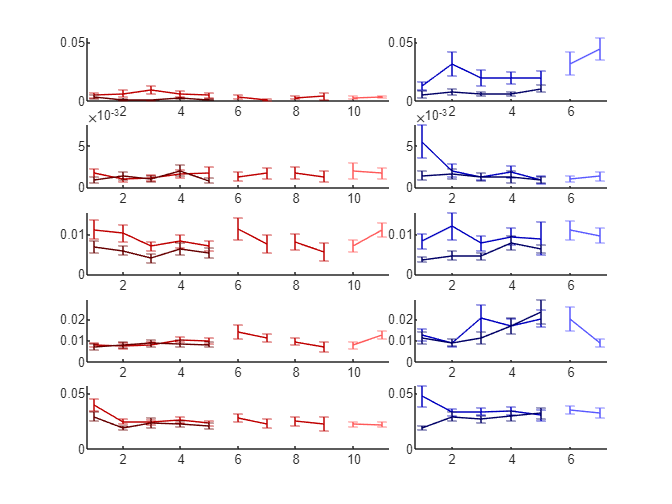

for i = 1:5
   ylim1 = get(sp1{i}, 'YLim');
   ylim2 = get(sp2{i}, 'YLim');
   maxlims = max([ylim1 ; ylim2]);
   set(sp1{i}, 'YLim', [0 maxlims(2)-.0]);
   set(sp2{i}, 'YLim', [0 maxlims(2)-.0]);
end


pint_t = nan(5,1);
pint_a = nan(5,2);

for i = 1:5
    pint_t(i) = stats_t{i}.pValue(3);
    for j = 1:2
        pint_a(i,j) = stats_a{i,j}.pValue(3);
        pint_a_i(i,j) = stats_a{i,j}.pValue(4);
    end
end


fdr_bh(pint_t)

ans = 5×1 logical array
   1
   1
   1
   0
   1


fdr_bh(pint_a(:,1))

ans = 5×1 logical array
   1
   0
   0
   0
   1


fdr_bh(pint_a(:,2))

ans = 5×1 logical array
   1
   1
   1
   0
   1



fdr_bh(pint_a_i(:,1))

ans =      0
     0
     0
     0
     0



fdr_bh(pint_a_i(:,2))

ans = 5×1 logical array
   0
   0
   0
   0
   1


## III. Individual variation in SvC differences

*Here we find that only the 30% "significant" animals show the stranger vs. cagemate effect (these are calculated in Part 0, and use an alpha of 0.1 across 5 sessions). Note that no animals were found to be significant in the other direction (higher in cagemate interactions).*

Repeat for only significant and only non-significant groups

for j = 1:2
    if j == 1
        dttT = dtt;
        indsigT = indsig;
        indnonsigT = indnonsig;
    else
        dttT = dttM;
        indsigT = indsigM;
        indnonsigT = indnonsigM;
    end

    allbyday = [dttT(indsigT, 6:10) ; dtt(indsigT, 11:15)].^(1/3);
    daymat = repmat(1:5, length(indsigT)*2, 1);
    dyadmat = repmat(1:length(indsigT)', 2, 5);
    cagVstr = [zeros(size(indsigT,1), 5) ; ones(length(indsigT), 5)];

    y_abd = reshape(allbyday, [],1);
    lin_days = reshape(daymat, [], 1);
    lin_degunum = reshape(dyadmat, [],1);
    lin_strcag  = reshape(cagVstr, [],1);

    abd_T_S = table(lin_degunum, lin_days, lin_strcag, y_abd);
    glme_S = fitglme(abd_T_S, 'y_abd ~ 1 + lin_strcag + lin_days + lin_strcag:lin_days + (1 | lin_degunum)');
    [~, ~, stats_S{j}] = fixedEffects(glme_S);
    stats_S{j}

    %[B, BINT, R, RINT, STATS] = regress(anovacell{1}, [ones(length(anovacell{1}),1) anovacell{2} anovacell{4} anovacell{2}.*anovacell{4}]);
    %B
    %BINT

    abd2 = cat(3,dttT(indsigT, 6:10) , dttT(indsigT, 11:15)).^(1/3);

    fprintf('sig -- sex: %d', j)
    tbl = simple_mixed_anova(abd2, [], {'exposureday' 'cagstr'})


    allbyday = [dttT(indnonsigT, 6:10) ; dtt(indnonsigT, 11:15)].^(1/3);
    daymat = repmat(1:5, length(indnonsigT)*2, 1);
    dyadmat = repmat(1:length(indnonsigT)', 2, 5);
    cagVstr = [zeros(size(indnonsigT,1), 5) ; ones(length(indnonsigT), 5)];

    y_abd = reshape(allbyday, [],1);
    lin_days = reshape(daymat, [], 1);
    lin_degunum = reshape(dyadmat, [],1);
    lin_strcag = reshape(cagVstr, [],1);

    abd_T_NS = table(lin_degunum, lin_days, lin_strcag, y_abd);
    glme_NS = fitglme(abd_T_NS, 'y_abd ~ 1 + lin_strcag + lin_days + lin_strcag:lin_days + (1 | lin_degunum)');
    [~, ~, stats_NS{j}] = fixedEffects(glme_NS);
    stats_NS{j}


    abd2 = cat(3,dttT(indnonsigT, 6:10) , dttT(indnonsigT, 11:15)).^(1/3);
    fprintf('nonsig -- sex: %d', j)
    tbl = simple_mixed_anova(abd2, [], {'exposurday' 'cagstr'})

end

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate     SE           tStat      DF     pValue        Lower        Upper    
    {'(Intercept)'        }          0.26751     0.025207     10.612    156    3.8074e-20      0.21772       0.3173
    {'lin_days'           }         0.009565    0.0067393     1.4193    156       0.15781    -0.003747     0.022877
    {'lin_strcag'         }          0.15079     0.035649     4.2298    156    3.9733e-05     0.080372       0.2212
    {'lin_days:lin_strcag'}        -0.013788    0.0095308    -1.4467    156       0.14999    -0.032614    0.0050381


sig -- sex: 1

tbl = 8×8 table
                                       SumSq      DF     MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    __    _________    _______    __________    __________    __________    __________

    (Intercept)                         19.703     1       19.703      463.6    1.0805e-12    1.0805e-12    1.0805e-12    1.0805e-12
    Error                              0.63749    15     0.042499                                                                   
    (Intercept):exposureday           0.023884     4     0.005971    0.89215       0.47431       0.44126       0.45714       0.3

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate       SE           tStat         DF     pValue        Lower        Upper    
    {'(Intercept)'        }            0.34041      0.01888         18.03    356    4.3126e-52      0.30328      0.37754
    {'lin_days'           }         -0.0054804    0.0044084       -1.2432    356       0.21462     -0.01415    0.0031893
    {'lin_strcag'         }         0.00028177     0.026701      0.010553    356       0.99159     -0.05223     0.052793
    {'lin_days:lin_strcag'}        -1.5928e-05    0.0062344    -0.0025548    356       0.99796    -0.012277     0.012245


nonsig -- sex: 1

tbl = 8×8 table
                                       SumSq       DF       MeanSq          F           pValue       pValueGG      pValueHF      pValueLB 
                                     __________    ___    __________    __________    __________    __________    __________    __________

    (Intercept)                          37.812      1        37.812        779.63    1.6413e-25    1.6413e-25    1.6413e-25    1.6413e-25
    Error                                1.6975     35      0.048499                                                                      
    (Intercept):exposurday             0.038773      4     0.0096932        1.5628       0.18758       0

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate      SE           tStat        DF    pValue        Lower        Upper   
    {'(Intercept)'        }           0.27803     0.033099          8.4    96    4.0174e-13      0.21233     0.34373
    {'lin_days'           }         0.0091329    0.0099797      0.91514    96       0.36241    -0.010677    0.028942
    {'lin_strcag'         }          0.063406     0.046809       1.3546    96       0.17874    -0.029509     0.15632
    {'lin_days:lin_strcag'}        -0.0012478     0.014113    -0.088415    96       0.92973    -0.029263    0.026767


sig -- sex: 2

tbl = 8×8 table
                                       SumSq      DF     MeanSq         F         pValue       pValueGG      pValueHF      pValueLB 
                                      ________    __    _________    _______    __________    __________    __________    __________

    (Intercept)                         14.647     1       14.647     662.66    9.7069e-10    9.7069e-10    9.7069e-10    9.7069e-10
    Error                              0.19894     9     0.022104                                                                   
    (Intercept):exposureday            0.01613     4    0.0040326    0.46157       0.76339       0.72581       0.76339       0.5

ans =     Fixed effect coefficients: DFMethod = 'residual', Alpha = 0.05

    Name                           Estimate     SE           tStat      DF     pValue        Lower        Upper     
    {'(Intercept)'        }          0.31609      0.01934     16.344    336    1.3504e-44      0.27804       0.35413
    {'lin_days'           }         0.017386    0.0046495     3.7393    336    0.00021687    0.0082402      0.026532
    {'lin_strcag'         }         0.035143      0.02735     1.2849    336        0.1997    -0.018656      0.088943
    {'lin_days:lin_strcag'}        -0.021584    0.0065755    -3.2825    336     0.0011369    -0.034518    -0.0086499


nonsig -- sex: 2

tbl = 8×8 table
                                      SumSq      DF      MeanSq        F        pValue      pValueGG     pValueHF     pValueLB 
                                     ________    ___    _________    ______    _________    _________    _________    _________

    (Intercept)                        48.945      1       48.945      1081    8.455e-27    8.455e-27    8.455e-27    8.455e-27
    Error                              1.4941     33     0.045276                                                              
    (Intercept):exposurday           0.037616      4    0.0094039    0.9894      0.41573      0.40287      0.40857      0.32713
    Error(ex

## IV. Use individual variation to interpret new cagemates and new strangers

*Here we run the analyses on new cagemates and new strangers*

Reminder of the variables. Note that nst is the combination of both new stranger sessions, and so-on across other

% for i = 1:size(dtt,1)
%     [h(i),p(i)] = ttest2(dtt(i,6:10).^(1/3), dtt(i,11:15).^(1/3));
%     svc(i) = nanmean(dtt(i,11:15).^(1/3) - dtt(i,6:10).^(1/3)); 
%     cag(i) = nanmean(dtt(i,6:10).^(1/3));
%     str(i) = nanmean(dtt(i,11:15).^(1/3));
%     nst(i) = nanmean(dtt(i,16:17).^(1/3));
%     ncg(i) = nanmean(dtt(i,21:25).^(1/3));
%     nc1(i) = nanmean(dtt(i,21:22).^(1/3));
%     nc2(i) = nanmean(dtt(i,23:24).^(1/3));
% end

SC-HIGH

New strangers differ from cagemates:


[a, b, ~, st] = ttest(nst(indsig)-cag(indsig))

a = 1

b = 8.1761e-04

st = struct with fields:
    tstat: 4.1722
       df: 15
       sd: 0.0818


cod_ost = nanmean(str(indsig)-cag(indsig))/nanstd(str(indsig)-cag(indsig))

cod_ost = 2.2831


cod_nst = nanmean(nst(indsig)-cag(indsig))/nanstd(nst(indsig)-cag(indsig))

cod_nst = 1.0430

New strangers not different from old strangers:

[a, b, ~, st] = ttest(nst(indsig)-str(indsig))

a = 0

b = 0.2772

st = struct with fields:
    tstat: -1.1277
       df: 15
       sd: 0.0854


SC-LOW


[a, b, ~, st] = ttest(nst(indnonsig)-cag(indnonsig))

a = 0

b = 0.6938

st = struct with fields:
    tstat: -0.3970
       df: 35
       sd: 0.0953


New strangers not different from old strangers:

[a, b, ~, st] = ttest(nst(indnonsig)-str(indnonsig))

a = 0

b = 0.6926

st = struct with fields:
    tstat: -0.3986
       df: 35
       sd: 0.0984


Strangers DO NOT differ from new cagemates:

notnanncg = intersect(indsig, find(~isnan(nc1)));

[a, b, ~, st] = ttest(str(notnanncg)-ncg(notnanncg))

a = 0

b = 0.6677

st = struct with fields:
    tstat: -0.4438
       df: 9
       sd: 0.0395


Cagemates differ from new cagemates

[a, b, ~, st] = ttest(cag(notnanncg)-ncg(notnanncg))

a = 1

b = 3.8008e-04

st = struct with fields:
    tstat: -5.5002
       df: 9
       sd: 0.0527


cod_cag_ncg = nanmean(cag(notnanncg)-ncg(notnanncg))/nanstd(cag(notnanncg)-ncg(notnanncg))

cod_cag_ncg = -1.7393

Strangers DO NOT differ from 1 week co-housed new cagemates

notnanncg2 = intersect(indsig, find(~isnan(nc2)));

[a, b, ~, st] = ttest(str(indsig)-nc2(indsig))

a = 0

b = 0.5114

st = struct with fields:
    tstat: 0.6917
       df: 7
       sd: 0.0477


Cagemates differ from 1 week co-housed new cagemates

[a, b, ~, st] = ttest(cag(notnanncg2)-nc2(notnanncg2))

a = 1

b = 0.0206

st = struct with fields:
    tstat: -2.9777
       df: 7
       sd: 0.0673


cod_cag_nc2 = nanmean(cag(notnanncg)-nc2(notnanncg))/nanstd(cag(notnanncg)-nc2(notnanncg))

cod_cag_nc2 = -1.0528

#### Males

[a, b, ~, st] = ttest(cag_m-nst_m)

a = 1

b = 6.6561e-06

st = struct with fields:
    tstat: -5.1277
       df: 43
       sd: 0.1022


[a, b, ~, st] = ttest(str_m-nst_m)

a = 0

b = 0.0859

st = struct with fields:
    tstat: -1.7575
       df: 43
       sd: 0.1005


## V. Figures taking into account individual variation

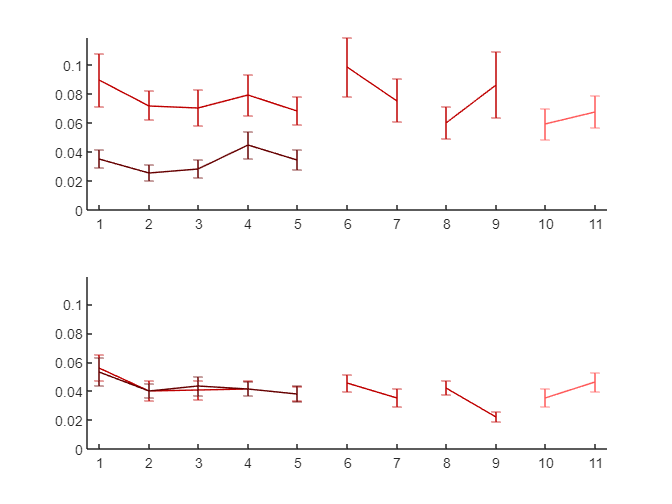





figure
subplot(2,1,1)
e1 = errorbar(1:5, nanmean(dtt(indsig,11:15)), nanstd(dtt(indsig,11:15))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(1,:));
hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
e2 = errorbar(1:5, nanmean(dtt(indsig,6:10)), nanstd(dtt(indsig,6:10))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

errorbar(10:11, nanmean(dtt(indsig,16:17)), nanstd(dtt(indsig,16:17))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(3,:))

%e1 = errorbar(1:5, nanmean(dttM(indsigM,11:15)), nanstd(dttM(indsigM,11:15))/sqrt(length(indsigM)-1), 'Color', colorcodes_mal(1,:));
hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
%e2 = errorbar(1:5, nanmean(dttM(indsigM,6:10)), nanstd(dttM(indsigM,6:10))/sqrt(length(indsigM)-1), 'Color', colorcodes_mal(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

%errorbar(1:2, nanmean(dttM(indsigM,16:17)), nanstd(dttM(indsigM,16:17))/sqrt(length(indsigM)-1), 'Color', colorcodes_mal(3,:))

errorbar(6:7, nanmean(dtt(indsig,21:22)), nanstd(dtt(indsig, 21:22)/sqrt(length(indsig)-1)), 'Color', colorcodes_fem(1,:));
errorbar(8:9, nanmean(dtt(indsig,23:24)), nanstd(dtt(indsig, 23:24)/sqrt(length(indsig)-1)), 'Color', colorcodes_fem(1,:));

set(get(e1, 'parent'), 'XLim', [0.75 11.25])
ylims = get(get(e1, 'parent'), 'YLim');
box off
subplot(2,1,2)
e1 = errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(1,:));
hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
e2 = errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

errorbar(10:11, nanmean(dtt(indnonsig,16:17)), nanstd(dtt(indnonsig,16:17))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(3,:))

%e1 = errorbar(1:5, nanmean(dttM(indnonsigM,11:15)), nanstd(dttM(indnonsigM,11:15))/sqrt(length(indnonsigM)-1), 'Color', colorcodes_mal(1,:));
%hold on

%e2 = errorbar(1:5, nanmean(dttM(indnonsigM,6:10)), nanstd(dttM(indnonsigM,6:10))/sqrt(length(indnonsigM)-1), 'Color', colorcodes_mal(2,:));


%errorbar(1:2, nanmean(dttM(indnonsigM,16:17)), nanstd(dttM(indnonsigM,16:17))/sqrt(length(indnonsigM)-1), 'Color', colorcodes_mal(3,:))



errorbar(6:7, nanmean(dtt(indnonsig,21:22)), nanstd(dtt(indnonsig, 21:22)/sqrt(length(indnonsig)-1)), 'Color', colorcodes_fem(1,:));
errorbar(8:9, nanmean(dtt(indnonsig,23:24)), nanstd(dtt(indnonsig, 23:24)/sqrt(length(indnonsig)-1)), 'Color', colorcodes_fem(1,:));
set(get(e1, 'parent'), 'XLim', [0.75 11.25])
set(get(e1, 'parent'), 'YLim', ylims);
box off

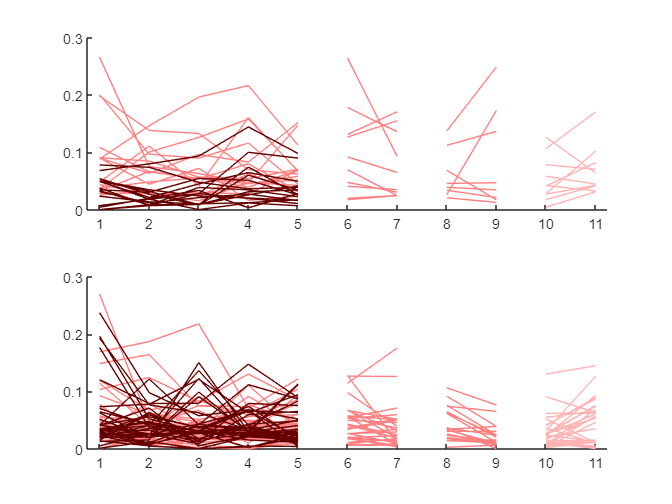


clear p1 p2 
figure
subplot(2,1,1)
hold on
for i = 1:size(indsig,1)
    p1{i} = plot(1:5, dtt(indsig(i),11:15), 'Color', [1 .5 .5]);
end

%sc1 = swarmchart(1:5, dtt(indsig,11:15), 'Color', colorcodes_fem(1,:));
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
for i = 1:size(indsig,1)
    p2{i} = plot(1:5, dtt(indsig(i),6:10), 'Color', [.4 0 0]); %[.85 .75 .75]);
end

%%UNCOMMENT TO ADD THE ERRORBARS
%e1 = errorbar(1:5, nanmean(dtt(indsig,11:15)), nanstd(dtt(indsig,11:15))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(1,:), 'LineWidth', 2);
%e2 = errorbar(1:5, nanmean(dtt(indsig,6:10)), nanstd(dtt(indsig,6:10))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(2,:), 'LineWidth', 2);


%sc2 = swarmchart(1:5, dtt(indsig,6:10), 'Color', colorcodes_fem(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

for i = 1:size(indsig,1)
    p1{i} = plot(10:11, dtt(indsig(i),16:17), 'Color', [1 .7 .7]);% [1 .9 .9]);
end

%%% UNCOMMENT TO ADD THE ERRORBARS
%errorbar(10:11, nanmean(dtt(indsig,16:17)), nanstd(dtt(indsig,16:17))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(3,:), 'LineWidth', 2)


%e1 = errorbar(1:5, nanmean(dttM(indsigM,11:15)), nanstd(dttM(indsigM,11:15))/sqrt(length(indsigM)-1), 'Color', colorcodes_mal(1,:));
hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
%e2 = errorbar(1:5, nanmean(dttM(indsigM,6:10)), nanstd(dttM(indsigM,6:10))/sqrt(length(indsigM)-1), 'Color', colorcodes_mal(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

%errorbar(1:2, nanmean(dttM(indsigM,16:17)), nanstd(dttM(indsigM,16:17))/sqrt(length(indsigM)-1), 'Color', colorcodes_mal(3,:))

for i = 1:size(indsig,1)
    p1{i} = plot(6:7, dtt(indsig(i),21:22), 'Color', [1 .5 .5]); %[1 .85 .85]);
end


%%UNCOMMENT TO ADD THE ERRORBARS
%errorbar(6:7, nanmean(dtt(indsig,21:22)), nanstd(dtt(indsig, 21:22)/sqrt(length(indsig)-1)), 'Color', colorcodes_fem(1,:), 'LineWidth', 2);

for i = 1:size(indsig,1)
    p1{i} = plot(8:9, dtt(indsig(i),23:24), 'Color', [1 .5 .5]); %[1 .85 .85]);
end

%%UNCOMMENT TO ADD THE ERRORBARS
%errorbar(8:9, nanmean(dtt(indsig,23:24)), nanstd(dtt(indsig, 23:24)/sqrt(length(indsig)-1)), 'Color', colorcodes_fem(1,:), 'LineWidth', 2);


set(get(p1{1}, 'parent'), 'XLim', [0.75 11.25])
ylims = get(get(p1{1}, 'parent'), 'YLim');
box off


% non-sig
%
%
%

subplot(2,1,2)
hold on
for i = 1:size(indnonsig,1)
    p1{i} = plot(1:5, dtt(indnonsig(i),11:15), 'Color', [1 .5 .5]);
end

%sc1 = swarmchart(1:5, dtt(indsig,11:15), 'Color', colorcodes_fem(1,:));
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
for i = 1:size(indnonsig,1)
    p2{i} = plot(1:5, dtt(indnonsig(i),6:10), 'Color', [.4 0 0]); % [.85 .75 .75]);
end

%e1 = errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(1,:), 'LineWidth', 2);

%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
%e2 = errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(2,:), 'LineWidth', 2);

%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);


for i = 1:size(indnonsig,1)
    p1{i} = plot(10:11, dtt(indnonsig(i),16:17), 'Color', [1 .7 .7]);
end

%%%UNCOMMENT FOR ERRORBARS
%errorbar(10:11, nanmean(dtt(indnonsig,16:17)), nanstd(dtt(indnonsig,16:17))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(3,:), 'LineWidth', 2)

%e1 = errorbar(1:5, nanmean(dttM(indnonsigM,11:15)), nanstd(dttM(indnonsigM,11:15))/sqrt(length(indnonsigM)-1), 'Color', colorcodes_mal(1,:));
%hold on

%e2 = errorbar(1:5, nanmean(dttM(indnonsigM,6:10)), nanstd(dttM(indnonsigM,6:10))/sqrt(length(indnonsigM)-1), 'Color', colorcodes_mal(2,:));


%errorbar(1:2, nanmean(dttM(indnonsigM,16:17)), nanstd(dttM(indnonsigM,16:17))/sqrt(length(indnonsigM)-1), 'Color', colorcodes_mal(3,:))

for i = 1:size(indnonsig,1)
    p1{i} = plot(6:7, dtt(indnonsig(i),21:22), 'Color', [1 .5 .5]);
end

for i = 1:size(indnonsig,1)
    p1{i} = plot(8:9, dtt(indnonsig(i),23:24), 'Color', [1 .5 .5]);
end


%%%Uncomment for errorbars
%errorbar(6:7, nanmean(dtt(indnonsig,21:22)), nanstd(dtt(indnonsig, 21:22)/sqrt(length(indnonsig)-1)), 'Color', colorcodes_fem(1,:), 'LineWidth', 2);
%errorbar(8:9, nanmean(dtt(indnonsig,23:24)), nanstd(dtt(indnonsig, 23:24)/sqrt(length(indnonsig)-1)), 'Color', colorcodes_fem(1,:), 'LineWidth', 2);
set(get(p1{1}, 'parent'), 'XLim', [0.75 11.25])
set(get(p1{1}, 'parent'), 'YLim', ylims);
box off

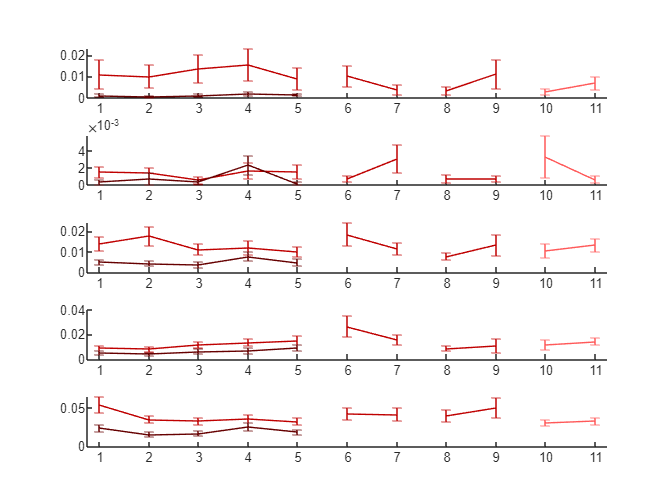


figure
for i = 1:5    
    subplot(5,1,i)

e1 = errorbar(1:5, nanmean(degutable(indsig,11:15, i)), nanstd(degutable(indsig,11:15,i))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(1,:));
hold on
%errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
e2 = errorbar(1:5, nanmean(degutable(indsig,6:10,i)), nanstd(degutable(indsig,6:10,i))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(2,:));
%errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

errorbar(10:11, nanmean(degutable(indsig,16:17,i)), nanstd(degutable(indsig,16:17,i))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(3,:));

errorbar(6:7, nanmean(degutable(indsig,21:22,i)), nanstd(degutable(indsig, 21:22,i)/sqrt(length(indsig)-1)), 'Color', colorcodes_fem(1,:));
errorbar(8:9, nanmean(degutable(indsig,23:24,i)), nanstd(degutable(indsig, 23:24,i)/sqrt(length(indsig)-1)), 'Color', colorcodes_fem(1,:));

set(get(e1, 'parent'), 'XLim', [0.75 11.25])
box off


end

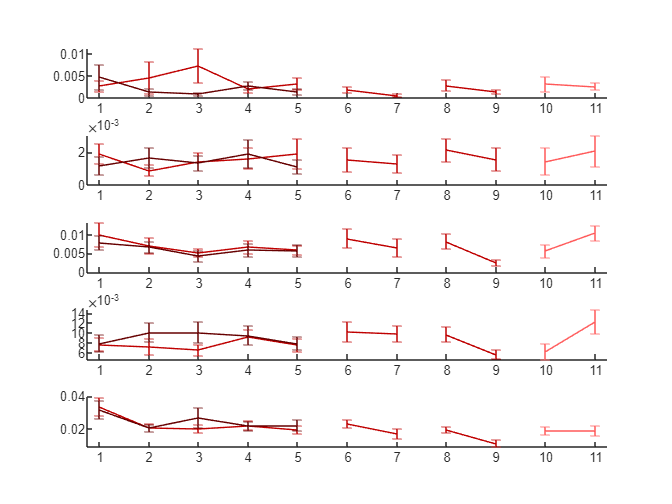




figure
for i = 1:5
    subplot(5,1,i)
    e1 = errorbar(1:5, nanmean(degutable(indnonsig,11:15, i)), nanstd(degutable(indnonsig,11:15,i))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(1,:));
    hold on
    %errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
    e2 = errorbar(1:5, nanmean(degutable(indnonsig,6:10,i)), nanstd(degutable(indnonsig,6:10,i))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(2,:));
    %errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);

    errorbar(10:11, nanmean(degutable(indnonsig,16:17,i)), nanstd(degutable(indnonsig,16:17,i))/sqrt(length(indnonsig)-1), 'Color', colorcodes_fem(3,:));

    errorbar(6:7, nanmean(degutable(indnonsig,21:22,i)), nanstd(degutable(indnonsig, 21:22,i)/sqrt(length(indnonsig)-1)), 'Color', colorcodes_fem(1,:));
    errorbar(8:9, nanmean(degutable(indnonsig,23:24,i)), nanstd(degutable(indnonsig, 23:24,i)/sqrt(length(indnonsig)-1)), 'Color', colorcodes_fem(1,:));

    set(get(e1, 'parent'), 'XLim', [0.75 11.25])
    box off
       
end

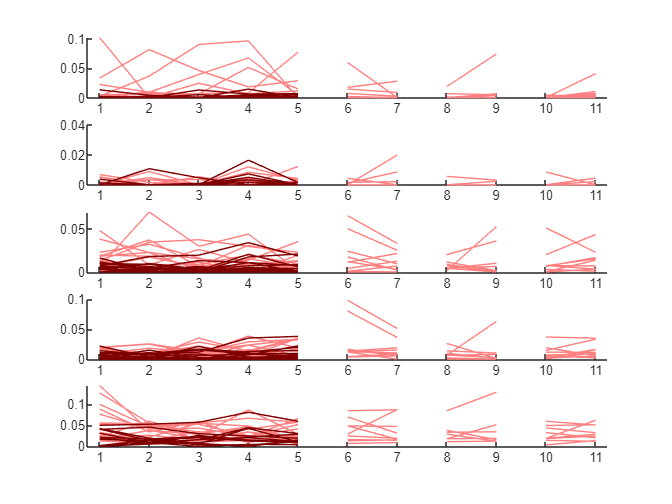

figure
for i = 1:5    
    subplot(5,1,i)
    hold on

    for j = 1:size(indsig,1)
        p1{j} = plot(1:5, degutable(indsig(j),11:15,i), 'Color', [1 .5 .5]);
    end

%    e1 = errorbar(1:5, nanmean(degutable(indsig,11:15, i)), nanstd(degutable(indsig,11:15,i))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(1,:), 'LineWidth', 1.5);


    for j = 1:size(indsig,1)
        p2{j} = plot(1:5, degutable(indsig(j),6:10,i), 'Color', [.5 0 0]);
    end
    %errorbar(1:5, nanmean(dtt(indnonsig,11:15)), nanstd(dtt(indnonsig,11:15))/sqrt(length(indnonsig)-1), 'Color', [.75 .25 .25])
%    e2 = errorbar(1:5, nanmean(degutable(indsig,6:10,i)), nanstd(degutable(indsig,6:10,i))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(2,:), 'LineWidth', 1.5);
    %errorbar(1:5, nanmean(dtt(indnonsig,6:10)), nanstd(dtt(indnonsig,6:10))/sqrt(length(indnonsig)-1), 'Color', [0.25 0.25 .25]);


    for j = 1:size(indsig,1)
        p2{j} = plot(10:11, degutable(indsig(j),16:17,i), 'Color', [1 .5 .5]);
    end
    
%    errorbar(10:11, nanmean(degutable(indsig,16:17,i)), nanstd(degutable(indsig,16:17,i))/sqrt(length(indsig)-1), 'Color', colorcodes_fem(3,:), 'LineWidth', 1.5);

    for j = 1:size(indsig,1)
        p2{j} = plot(6:7, degutable(indsig(j),21:22,i), 'Color', [1 .5 .5]);
    end

%    errorbar(6:7, nanmean(degutable(indsig,21:22,i)), nanstd(degutable(indsig, 21:22,i)/sqrt(length(indsig)-1)), 'Color', colorcodes_fem(1,:), 'LineWidth', 1.5);

    for j = 1:size(indsig,1)
        p2{j} = plot(8:9, degutable(indsig(j),23:24,i), 'Color', [1 .5 .5]);
    end  
    
%    errorbar(8:9, nanmean(degutable(indsig,23:24,i)), nanstd(degutable(indsig, 23:24,i)/sqrt(length(indsig)-1)), 'Color', colorcodes_fem(1,:), 'LineWidth', 1.5);

    set(get(p1{j}, 'parent'), 'XLim', [0.75 11.25])
    box off


end


for i = 1:5
    [a b(i)] = ttest(degutable(indnonsig, 5+i, 1) - degutable(indnonsig,10+i,1));
end
b

b =     0.4361    0.3500    0.0848    0.4935    0.2625



avinteract_cag = nanmean(dtt(:,6:10), 2);
stinteract_all = nanstd(dtt(:,6:17), [],2);
avinteract_str = nanmean(dtt(:,11:15), 2);
avinteract_nst = nanmean(dtt(:,16:17), 2);

figure
hold

Current plot held


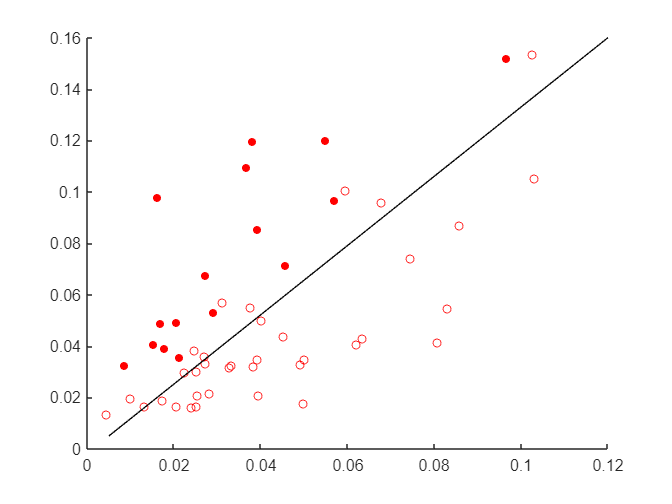

plot(avinteract_cag(indsig), avinteract_str(indsig), '.', 'Color', [1 0 0], 'Markersize', 15);
plot(avinteract_cag(indnonsig), avinteract_str(indnonsig), 'o', 'Color', [1 0 0], 'Markersize', 5);
plot([.005 .12], [.005 .16], 'k')
box off

nonsibling_ind = find(rdb_rr.strangernum == 0 & floor(rdb_rr.deguA/100) ~= floor(rdb_rr.deguB/100));
allnonsib = unique([rdb_rr.deguA(nonsibling_ind) ; rdb_rr.deguB(nonsibling_ind)]);
indns = find(ismember(dtt(:,1), allnonsib));
ismember(indns, indnonsig);

figure
hold

Current plot held


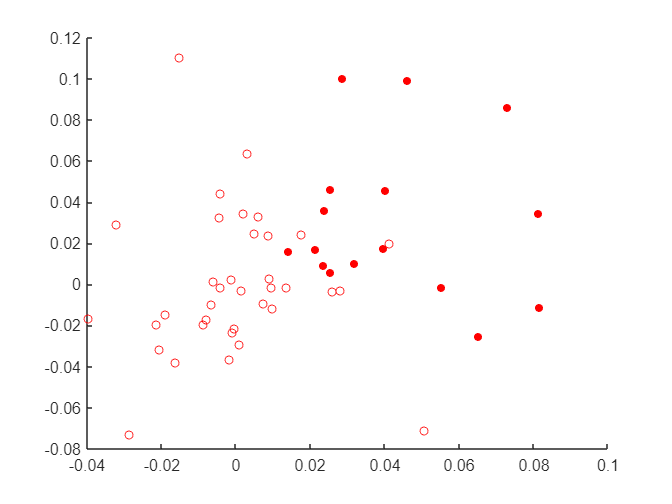

plot(avinteract_str(indsig) - avinteract_cag(indsig), avinteract_nst(indsig) - avinteract_cag(indsig), '.', 'Color', [1 0 0], 'MarkerSize', 15);
plot(avinteract_str(indnonsig) - avinteract_cag(indnonsig), avinteract_nst(indnonsig) - avinteract_cag(indnonsig), 'o', 'Color', [1 0 0], 'MarkerSize', 5);
box off

figure
hold

Current plot held


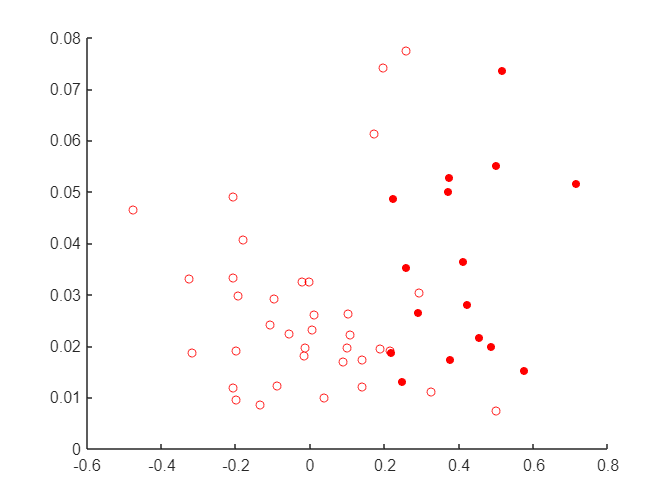

plot((avinteract_str(indsig) - avinteract_cag(indsig))./(avinteract_str(indsig) + avinteract_cag(indsig)), stinteract_all(indsig), '.', 'Color', [1 0 0], 'MarkerSize', 15);
plot((avinteract_str(indnonsig) - avinteract_cag(indnonsig))./(avinteract_str(indnonsig) + avinteract_cag(indnonsig)), stinteract_all(indnonsig), 'o', 'Color', [1 0 0], 'MarkerSize', 5);
box off




figure
hold

Current plot held


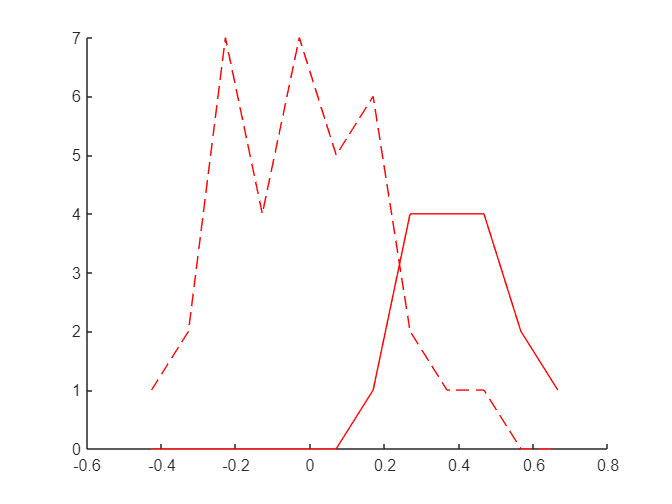

sc_diffscore = (avinteract_str - avinteract_cag)./(avinteract_str + avinteract_cag);
[a b] = hist(sc_diffscore, 12);
[aS, bS] = hist(sc_diffscore(indsig), b);
[aNS, bNS] = hist(sc_diffscore(indnonsig), b);
%plot(b, a, 'Color', [.7 .7 .7])
plot(b, aNS, 'LineStyle', '--', 'Color', 'r')
plot(b, aS, 'r');
box off

## VII. Individual differences across interaction types

*Quick comparison across interaction types. Figures are misleading because do not take into account that only a subset of animals were 1-week co-housed as new strangers. Stats are more informative. *

Are new cagemates high levels of interaction because they're relying on different interaction types?

h = nan(size(dtt,1),1);
p = h;
clear st1 st2 st3 st4 cag3 str3 ncg3 nc13 nc23 svc3 a1 b1 a2 b2 a3 b3 a4 b4

for j = 1:size(degutable,3)
for i = 1:size(dtt,1)
%    [h(i),p(i)] = ttest2(degutable(i,6:10,j).^(1/3), degutable(i,11:15,j).^(1/3));
    svc3(i,j) = nanmean(squeeze(degutable(i,11:15,j))'.^(1/3) - squeeze(degutable(i,6:10,j))'.^(1/3)); 
    cag3(i,j) = nanmean(squeeze(degutable(i,6:10,j))'.^(1/3));
    str3(i,j) = nanmean(squeeze(degutable(i,11:15,j))'.^(1/3));
    nst3(i,j) = nanmean(squeeze(degutable(i,16:17,j))'.^(1/3));
    ncg3(i,j) = nanmean(squeeze(degutable(i,23:24,j))'.^(1/3));
    nc13(i,j) = nanmean(squeeze(degutable(i,21:22,j))'.^(1/3));
    nc23(i,j) = nanmean(squeeze(degutable(i,23:24,j))'.^(1/3));

    if i <= size(dttM,1)
        cag3M(i,j) = nanmean(squeeze(degutableM(i,6:10,j))'.^(1/3));
        str3M(i,j) = nanmean(squeeze(degutableM(i,11:15,j))'.^(1/3));
        nst3M(i,j) = nanmean(squeeze(degutableM(i,16:17,j))'.^(1/3));
    end
end


[a1(j), b1(j), ~, st1(j)] = ttest(nc13(indsig,j)-cag3(indsig,j));%
[a2(j), b2(j), ~, st2(j)] = ttest(nc13(indsig,j)-str3(indsig,j));%

cod_nc13_str(j) = nanmean(nc13(indsig,j)-cag3(indsig,j))/nanstd(nc13(indsig,j)-cag3(indsig,j));

[a3(j), b3(j), ~, st3(j)] = ttest(nc23(indsig,j)-cag3(indsig,j));
[a4(j), b4(j), ~, st4(j)] = ttest(nc23(indsig,j)-str3(indsig,j));

cod_nc23_str(j) = nanmean(nc23(indsig,j)-cag3(indsig,j))/nanstd(nc23(indsig,j)-cag3(indsig,j));

[a5(j), b5(j), ~, st5(j)] = ttest(nst3(indsig,j)-cag3(indsig,j));
[a6(j), b6(j), ~, st6(j)] = ttest(nst3(indsig,j)-str3(indsig,j));

cod_nst_cag(j) = nanmean(nst3(indsig,j)-cag3(indsig,j))/nanstd(nst3(indsig,j)-cag3(indsig,j));

[a7(j), b7(j), ~, st7(j)] = ttest(nst3M(:,j)-cag3M(:,j));
[a8(j), b8(j), ~, st8(j)] = ttest(nst3M(:,j)-str3M(:,j));


end

cod_nc13_str

cod_nc13_str =     0.3549    0.6091    1.0053    0.6257    1.5869



cod_nc23_str

cod_nc23_str =     0.3780    0.3501    0.6124   -0.2006    1.0947



cod_nst_cag

cod_nst_cag =     0.5571    0.2621    0.5110    0.5293    1.0262



b1

b1 =     0.2907    0.0862    0.0112    0.0792    0.0007


fdr_bh(b1)

ans = 1×5 logical array
   0   0   1   0   1


b2

b2 =     0.8157    0.5736    0.6028    0.3932    0.4646


fdr_bh(b2)

ans =      0     0     0     0     0


b3

b3 =     0.3205    0.3551    0.1269    0.5882    0.0174


fdr_bh(b3)

ans =      0     0     0     0     0


b4

b4 =     0.8509    0.6825    0.2812    0.0235    0.5646


fdr_bh(b4)

ans =      0     0     0     0     0


b5

b5 =     0.0416    0.3110    0.0589    0.0514    0.0009


fdr_bh(b5)

ans = 1×5 logical array
   0   0   0   0   1



b6

b6 =     0.5175    0.9112    0.7872    0.8679    0.2102


fdr_bh(b6)

ans =      0     0     0     0     0


#### MALES

b7

b7 =     0.0000    0.8445    0.0231    0.8634    0.1579


fdr_bh(b7)

ans = 1×5 logical array
   1   0   0   0   0



b8

b8 =     0.0019    0.1369    0.1668    0.7894    0.5654


fdr_bh(b8)

ans = 1×5 logical array
   1   0   0   0   0


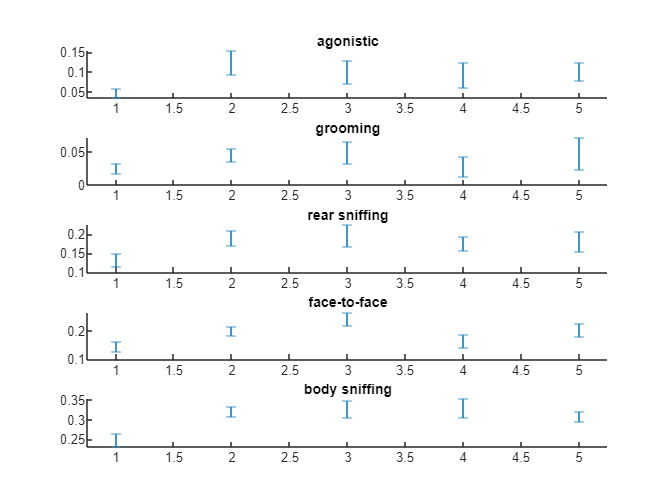

titlecell = {'agonistic', 'grooming', 'rear sniffing', 'face-to-face', 'body sniffing'};
figure
for j = 1:5
    a = subplot(5,1,j);
    errorbar(nanmean([cag3(indsig,j) str3(indsig,j) nc13(indsig,j) nc23(indsig,j) nst3(indsig,j)]), nanstd([cag3(indsig,j) str3(indsig,j) nc13(indsig,j) nc23(indsig,j) nst3(indsig,j)])/sqrt(length(indsig)-1), 'LineStyle', 'none' );
    
%       set(d, 'XLim', [.75 5.25]);
   title(titlecell{j});
   box off
   set(a, 'Xlim', [0.75 5.25]);
end